# Lab 5

# Higgs Classification

In this problem we are going to look at an inclusive search for the standard model Higgs boson in proton to proton  collisions at 13 TeV at the Large Hadron Collider (LHC) using simulated data [A. Schuy](https://github.com/AlexSchuy/qsvm_jet_tagging/tree/master/qsvm_jet_tagging/generation). 

The Higgs boson is why the subatomic particles gained mass. The Higgs boson are elementary particles that create the Higgs filed. When all subatomic particles pass through and interact with the Higgs field. When the interaction is small the mass is small. When the interaction is big the mass is big. 

The LHC is a very large ring shaped machine located in Geneva Switzerland. The LHC sends beams of the charged protons in opposite direction through the large ring and constantly make it move faster untill they collide. After the collision there will be many datas for scientists to study. Including the interaction with the Higgs filed. Collision exposed many types of subatomic particles and some time the Higgs boson can be detected. 

The Higgs bosons are produced with large transverse momentum (pT) and decaying to a bottom quark-antiquark pair. The Higgs candidates could be reconstructed as large-radius jets using Calorimeters.

In this problem I will use the same training samples for analysis. Each sample contains 14 features: ‘pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', 't1', 't2', 't3', 't21', 't32', 'KtDeltaR' [[Eur. Phys. J. C 79 (2019) 836](https://atlas.web.cern.ch/Atlas/GROUPS/PHYSICS/PAPERS/PERF-2017-04/)].

- pt - the transverse momentum  of the proton to proton collisions in the LHC. It is in xy-plane.

- eta - the pseudorapidity,the angle of the particle in the z-y plane.

- phi - The azimuthal angle, the angle of the particle in x-y plane.

- mass - invariant mass, the portion of the total mass of an object or system of objects that is independent of the overall motion of the system.

- ee2 - 2-point ECF ratio

- ee3 - 3-point ECF ratio

- d2 - 3 to 2 point ECF ratio

- angularity - Specific orientation of one feature to another at a referenced angle.

- t1 - 1-subjettiness

- t2 - 2-subjettiness

- t3 - 3-subjettiness

- t21 - 21-subjettiness

- t32 - 32-subjettiness

- KtDeltaR - delta R of two subjets within the large-R jet

N- subjettiness -  a jet shape designed to identify boosted hadronic objects such as top quarks. Given N subjet axes within a jet, N-subjettiness sums the angular dis- tances of jet constituents to their nearest subjet axis.

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


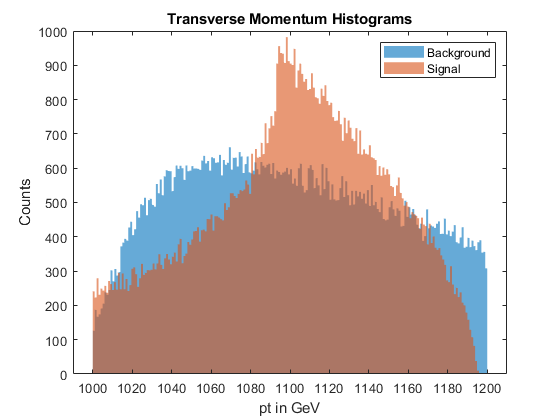

signal_dataset = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
background_dataset = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
signal_pt = signal_dataset(1,:);
signal_eta = signal_dataset(2,:);
signal_phi = signal_dataset(3,:);
signal_mass = signal_dataset(4,:);
signal_ee2 = signal_dataset(5,:);
signal_ee3 = signal_dataset(6,:);
signal_d2 = signal_dataset(7,:);
signal_angularity = signal_dataset(8,:);
signal_t1 = signal_dataset(9,:);
signal_t2 = signal_dataset(10,:);
signal_t3 = signal_dataset(11,:);
signal_t21 = signal_dataset(12,:);
signal_t32 = signal_dataset(13,:);
signal_KtDeltaR = signal_dataset(14,:);
background_pt = background_dataset(1,:);
background_eta = background_dataset(2,:);
background_phi = background_dataset(3,:);
background_mass = background_dataset(4,:);
background_ee2 = background_dataset(5,:);
background_ee3 = background_dataset(6,:);
background_d2 = background_dataset(7,:);
background_angularity = background_dataset(8,:);
background_t1 = background_dataset(9,:);
background_t2 = background_dataset(10,:);
background_t3 = background_dataset(11,:);
background_t21 = background_dataset(12,:);
background_t32 = background_dataset(13,:);
background_KtDeltaR = background_dataset(14,:);

figure;
histogram(background_pt,200,"EdgeColor","none")
hold on
histogram(signal_pt,200,"EdgeColor","none")
title("Transverse Momentum Histograms");
legend("Background","Signal");
xlabel("pt in GeV"); 
ylabel("Counts");

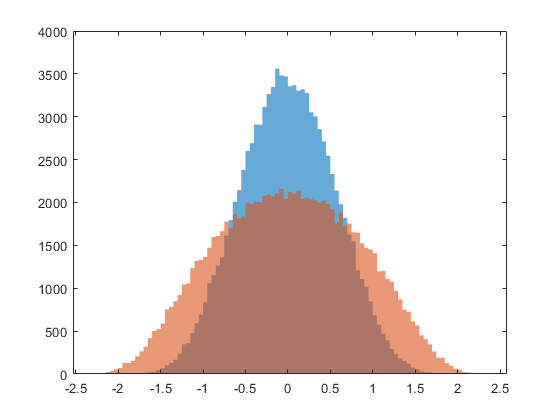



figure;
histogram(signal_eta,"EdgeColor","none")
hold on
histogram(background_eta,"EdgeColor","none")

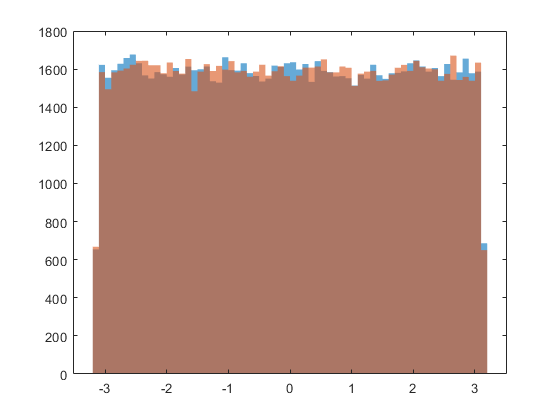


figure;
histogram(signal_phi,"EdgeColor","none")
hold on
histogram(background_phi,"EdgeColor","none")

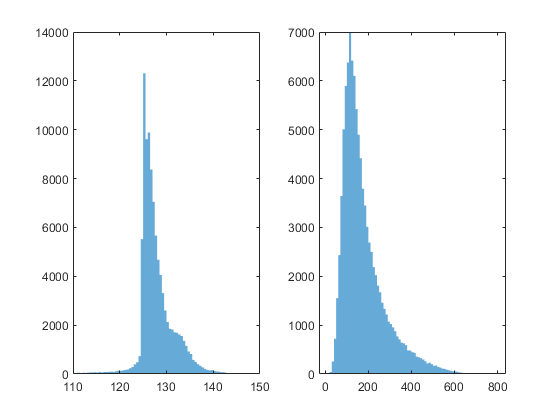

figure;
subplot(1,2,1)
histogram(signal_mass,"EdgeColor","none")
xlim([110 150])
subplot(1,2,2)
histogram(background_mass,"EdgeColor","none")

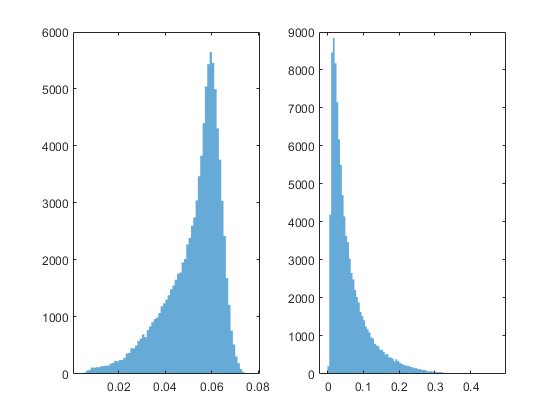

figure;
subplot(1,2,1)
histogram(signal_ee2,"EdgeColor","none")
subplot(1,2,2)
histogram(background_ee2,"EdgeColor","none")

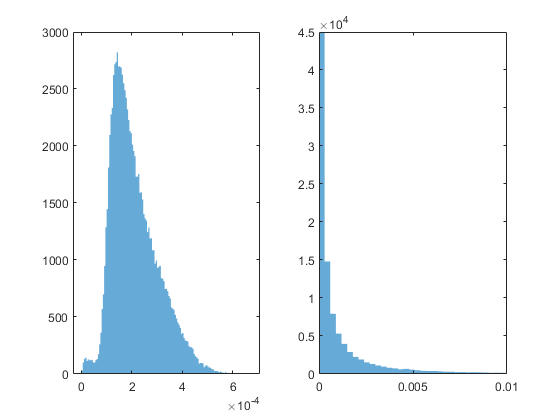

figure;
subplot(1,2,1)
histogram(signal_ee3,"EdgeColor","none")
subplot(1,2,2)
histogram(background_ee3,"EdgeColor","none")
xlim([0 0.01])

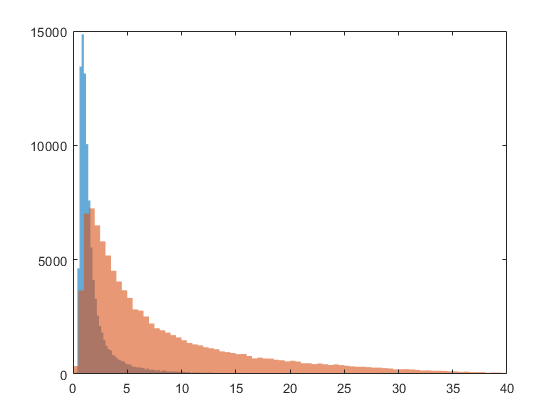

figure;
histogram(signal_d2,"EdgeColor","none")
hold on
histogram(background_d2,"EdgeColor","none")
xlim([0 40])

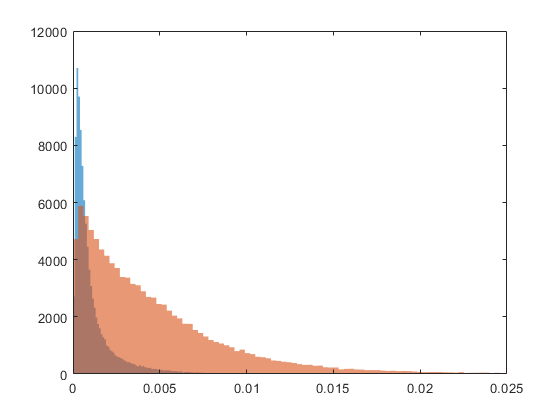

figure;
histogram(signal_angularity,"EdgeColor","none")
hold on
histogram(background_angularity,"EdgeColor","none")
xlim([0 0.025])

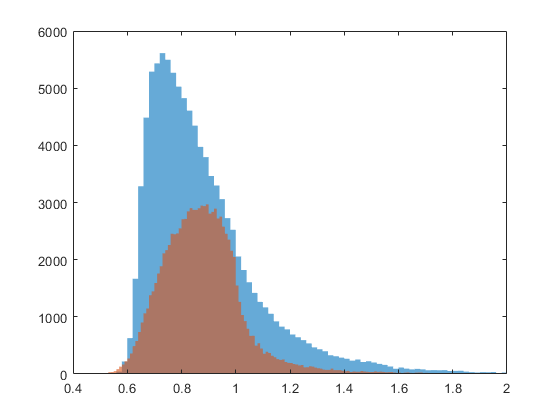

figure;
histogram(signal_t1,"EdgeColor","none")
hold on
histogram(background_t1,"EdgeColor","none")
xlim([0.4 2])

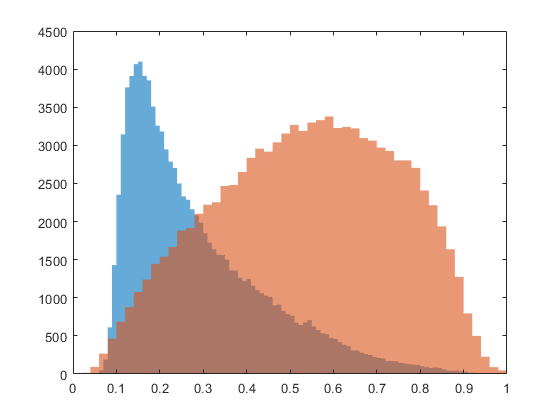

figure;
histogram(signal_t2,"EdgeColor","none")
hold on
histogram(background_t2,"EdgeColor","none")
xlim([0 1])

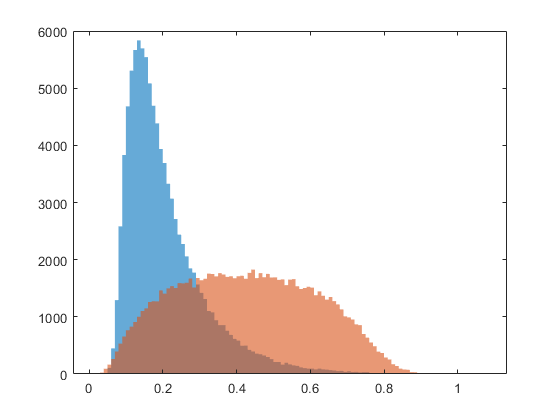

figure;
histogram(signal_t3,"EdgeColor","none")
hold on
histogram(background_t3,"EdgeColor","none")

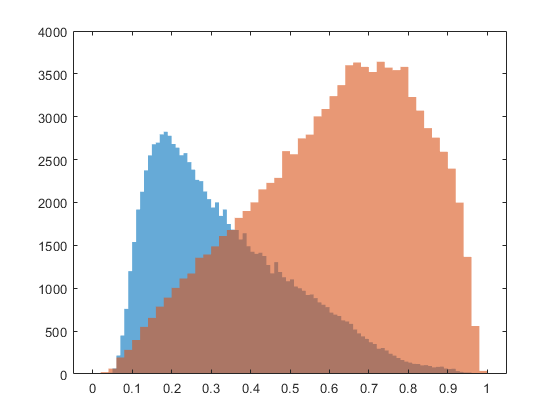

figure;
histogram(signal_t21,"EdgeColor","none")
hold on
histogram(background_t21,"EdgeColor","none")

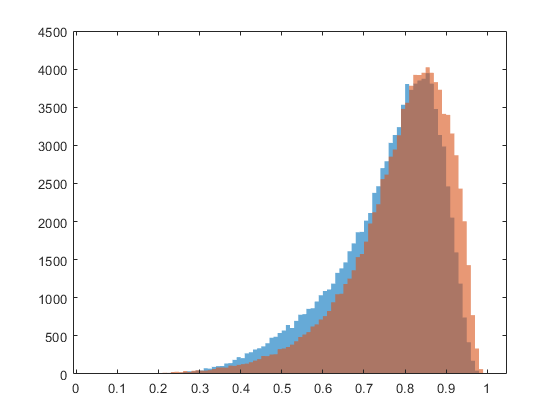

figure;
histogram(signal_t32,"EdgeColor","none")
hold on
histogram(background_t32,"EdgeColor","none")

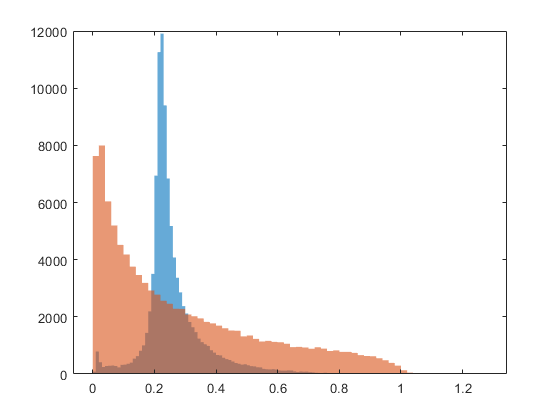

figure;
histogram(signal_KtDeltaR,"EdgeColor","none")
hold on
histogram(background_KtDeltaR,"EdgeColor","none")